# **Sesion 2.4.- Creación de un robot con RigidBodyTree: colisiones y visuals**

## Importar robot

clear;
close all;

Se definen los parámetros DH del robot manipulador planar de 4gdl

nJoints = 4;
a = 0.3;
dhparams = [a  0   0  0;
            a  0   0  0;
            a  0   0  0;
            a  0   0  0];

Se crea el objeto *rigidBodyTree*

%Creamos el objeto rigidBodyTree
robot = rigidBodyTree ('DataFormat', 'column');

%Utilizamos bucle for para construir todo el robot
bodies = cell(nJoints,1);
joints = cell(nJoints,1);
for i = 1:nJoints
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    setFixedTransform(joints{i},dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(robot,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(robot,bodies{i},bodies{i-1}.Name)
    end
end

%Verificamos
showdetails(robot)

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


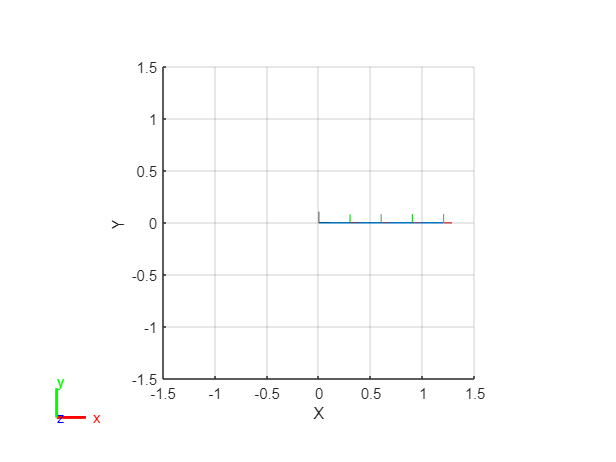

figure
show(robot);
view (2)
ax = gca; 
ax.Projection = 'orthographic';  

## Añadir colisiones

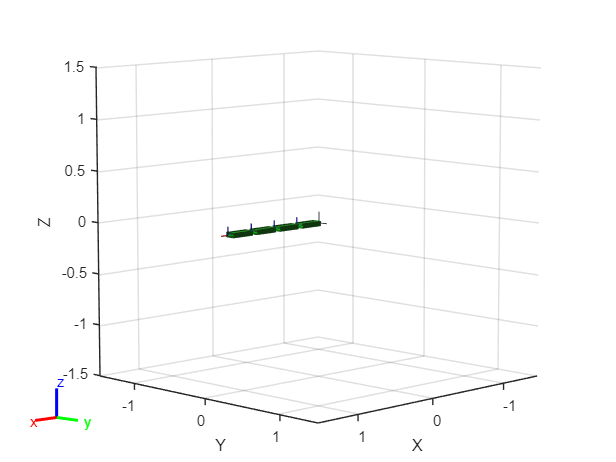

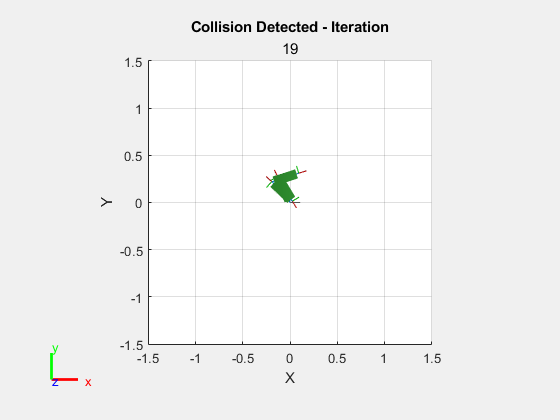

formaGeometrica = "Prisma";

for i = 1:robot.NumBodies
    clearCollision(robot.Bodies{i})
end


switch formaGeometrica
    case 'Cilindro'
        collisionObj = collisionCylinder(0.02, a-0.05);  %radious, length
        collisionObj.Pose = trvec2tform([-a/2, 0, 0])*eul2tform([0, pi/2, 0]);
    case 'Prisma'
         collisionObj = collisionBox (a-0.05, 0.1, 0.05);
         collisionObj.Pose = trvec2tform([-a/2, 0, 0]);
end


for i = 1:robot.NumBodies
    addCollision(robot.Bodies{i},collisionObj)
end


show(robot,'Collisions','on','Visuals','off');
figure
set(gcf,'Visible','on')
rng(0) % Set random seed for repeatability.
for i = 1:20
    config = randomConfiguration(robot);
    isColliding = checkCollision(robot,config);
    if isColliding
        show(robot,config,'Collisions','on','Visuals','off');
        view (2)
        ax = gca; 
        ax.Projection = 'orthographic';  
        title('Collision Detected - Iteration', num2str(i))
        pause (2)
    else
        % Skip non-collisions.
    end
end

## Añadir 'visuals'

Se pueden añadir geometricas visuales a los eslabones (body) de los robots definidos (rigidbodytree). Por ejemplo, se puede importar geometrías mediante un fichero .stl mediante la función [`addVisual`](https://es.mathworks.com/help/robotics/ref/rigidbody.addvisual.html). 

Nota: Matlab consideras las unidades de los ficheros stl en metros.

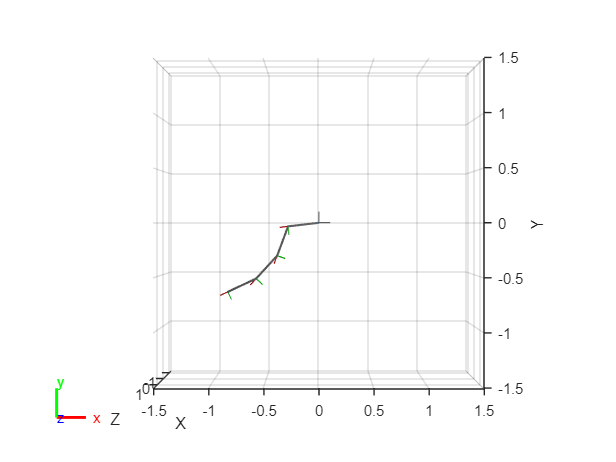

figure 
tt = trvec2tform([-a, 0, 0]);
for i = 1:robot.NumBodies
    addVisual(robot.Bodies{i},"Mesh", './modelos/Eslabon_MOD.stl',tt)
end

config = randomConfiguration(robot);

show(robot, config, 'Collisions','off','Visuals','on');
view(2)